# Partial derivatives and Tangent plane

## Introduction

The **essence** of calculus is the **derivative**. The **derivative** is the instantaneous rate of change of a function with respect to one of its variables. This is equivalent to finding the slope of the tangent line to the function at a point.

You already have learned some methods to calculate derivatives of functions and MATLAB can assist you to confirm your results or analyse the behaivour of the derivative graphically.

In this activity we will use the commands [`syms`](https://au.mathworks.com/help/symbolic/syms.html) and [`diff`](https://au.mathworks.com/help/symbolic/differentiation.html) to calculate partial derivatives symbolically and we will learn how to plot tangent planes to surfaces.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

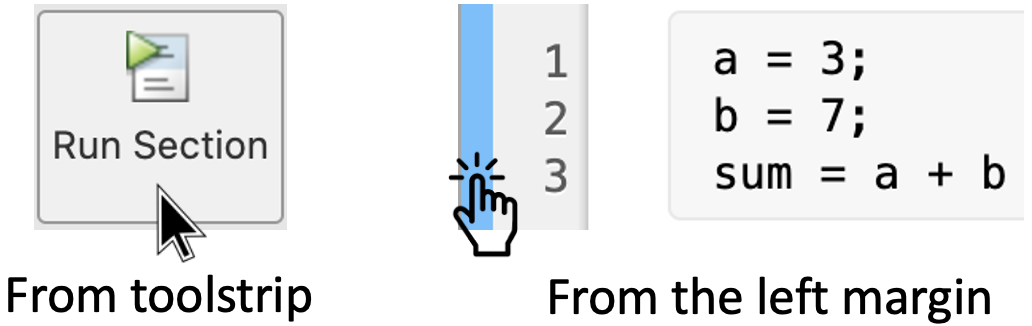

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Symbolic calculation of derivatives and partial derivatives

### 1.2 One variable functions

To illustrate how to calculate derivatives of one variable functions in MATLAB, first we create a [symbolic expression](https://au.mathworks.com/help/symbolic/syms.html):

syms x            % Define the symbolic variable x
f = 1/(1 + x^2);  % Define the symbolic expression, i.e. f(x)

The command

diff(f)

differentiates "`f`" with respect to "`x`". Run this section to see the result.

### 1.2 Multivariate functions

If we wish to compute the partial derivatives of a multivariate function we must specify the variable. That is, [`diff(f, var)`](https://au.mathworks.com/help/symbolic/diff.html?searchHighlight=derivatives&s_tid=srchtitle_derivatives_2#btwp767-1). For example, consider the function:


$$f(x)=(x+y)\cos(x-y)$$


In order to compute $\frac{\partial f}{\partial x}$ and $\frac{\partial f}{\partial y}$ we write the code:

syms x y
f = (x + y) * cos(x - y);
partialX = diff(f, x)
partialY = diff(f, y)

Run this section to see the output. Compute the partial derivatives in your notebook to confirm the results.

### 1.3 Second order derivatives of multivariate functions

In MATLAB we can also easily compute second-order derivatives of multivariate functions with respect to a particular variable.

For example, consider the function


$$f(x)=(x+2y)^3$$


In order to compute the second order partial derivatives

$\frac{\partial^2f}{\partial x^2}$,  $\frac{\partial^2f}{\partial y^2}$,  $\frac{\partial^2f}{\partial x \partial y}$ and $\frac{\partial^2f}{\partial y \partial x}$, 

 we write the code:

syms x y
f = (x + 2*y)^3;
secPartialX = diff(f, x, 2)
secPartialY = diff(f, y, 2)
secPartialXY = diff(f, x, y)
secPartialYX = diff(f, y, x)

**Note 1:** The code `diff(f,x,2)` is equivalent to `diff(f,x,x)`, and `diff(diff(f))` is equivalent to `diff(x*y,x,y)`. You can also compute higher-order derivatives. To learn more about it see: [Higher-order derivatives](https://au.mathworks.com/help/symbolic/diff.html#btwp91l-1).

## 2. Calculate and plot tangent plane to surface

Recall that the equation of the tangent plane to a given surface $z=f(x,y)$ at $\left(x_0,y_0,f(x_0,y_0)\right)$ is

$z= f(x_0,y_0)+\frac{\partial f(x_0,y_0)}{\partial x}(x-x_0)+\frac{\partial f(x_0,y_0)}{\partial y}(y-y_0)$.

This means that we need to evaluate the partial derivatives 

$\frac{\partial f}{\partial x}$ and $\frac{\partial f}{\partial y}$ at $(x_0,y_0)$.

The following example shows how to plot a tangent plane to a point on the surface by using the approximated values of *gradient vectors* of $z=f(x,y)$.

**Definition:** The **gradient vecto**r or simply **gradient** of $f(x,y)$ is a vector with the partial derivatives as components. That is:


$$\text{grad} f =\nabla f =\left( \frac{\partial f}{\partial x}, \frac{\partial f}{\partial y} \right)$$


**2.1 Step 1**

First, create the function $f(x,y)=x^2+y^2$ using a [function handle](https://au.mathworks.com/help/matlab/function-handles.html).

#### 2.2 Step 2

Approximate the partial derivatives of $f(x,y)$ with respect to $x$ and $y$ by using the command `gradient()`. Choose a finite difference length that is the same as the mesh size.

**Note 2:** The command [`meshgrid()`](https://au.mathworks.com/help/matlab/ref/meshgrid.html) is used to compute the domain of the function and the command [`gradient()`](https://au.mathworks.com/help/matlab/ref/gradient.html) computes the numerical gradient of $f$ evaluated at each point on the domain.

#### 2.3 Step 3

The tangent plane to a point on the surface, $P=(x_0,y_0,f(x_0,y_0))$, is given by

$z= f(x_0,y_0)+\frac{\partial f(x_0,y_0)}{\partial x}(x-x_0)+\frac{\partial f(x_0,y_0)}{\partial y}(y-y_0)$.

The `fx` and `fy` matrices defined in **Step 2** are approximations to the partial derivatives $\frac{\partial f}{\partial x}$ and $\frac{\partial f}{\partial y}$. The point of interest in this example, where the tangent plane meets the functional surface, is `(x0,y0) = (1,2)`. The value of this function at this point of interest is `f(1,2) = 5`.

Thus, to approximate the tangent plane $z$ we need to find the value of the derivatives at `(1,2)`. Obtain the index of that point, and find the approximate derivatives there. That is:

**Note 3:** Here we used the command [`find()`](https://au.mathworks.com/help/matlab/ref/find.html) to find indices and values of nonzero elements.

#### 2.4 Step 4

Create a function handle with the equation of the tangent plane `z`.

#### 2.5 Step 5

Finally, plot the original function $f(x,y)$, the point $P$, and a piece of plane $z$ that is tangent to the function at $P$.

**Note 4:** The command [`surf()`](https://au.mathworks.com/help/matlab/ref/surf.html) is used to plot the surface and the tangent plane. On the other hand, the command [`plot3()`](https://au.mathworks.com/help/matlab/ref/plot3.html) is used to plot the point of intersection `(1,2,5)`.

Thus, the complete code is the following. Run this section to see the output.

clf
% Step 1: Define function
f = @(x,y) x.^2 + y.^2;

% Step 2: Numerical gradient
[xx,yy] = meshgrid(-5:0.25:5);
[fx,fy] = gradient(f(xx,yy),0.25);

% Step 3: Compute value of the derivatives at (x0, y0)
x0 = 1;
y0 = 2;
t = (xx == x0) & (yy == y0);
indt = find(t);
fx0 = fx(indt);
fy0 = fy(indt);

% Step 4: Define tanget plane at (x0, y0)
z = @(x,y) f(x0,y0) + fx0*(x-x0) + fy0*(y-y0);

% Plot surface and tangent plane
surf(xx,yy,f(xx,yy),'EdgeAlpha',0.7,'FaceAlpha',0.9)
hold on
surf(xx,yy,z(xx,yy))
plot3(1,2,f(1,2),'r*')
% view(-135,9) % Uncomment this line to change the 3D view

## 3. Hands on practice

#### Activity 1: 

Compute all the second partial derivatives of the following functions:

- 
$$f_1(x,y) = \exp(xy)\sin (y)$$
 

- 
$$f_2(x,t) =\sqrt{3x+4t}$$


- 
$$f_3(x,y) = \frac{xy}{1+x^2+y^2}$$


- 
$$f_4(u,v) = \exp\left(-\frac{u^2+v^2}{3}\right)\big(\sin u^2 + \cos v^2\big)$$


Write your code here:

% Part 1:


% Part 2:


% Part 3:


% Part 4:



#### Activity 2:

**Problem 1** - Plot the tangent plane of $z=1-x^2-y^2$ at $(1,-1,-1)$.

Write your code here:

**Problem 2** - Plot the tangent plane of $z=\sqrt{9+x^2y^2}$ at $(2,2,5)$.

Write your code here: